# Gyakorlat 1

Vektor definiálása elemenként.

v = [1 5 7]

v =      1     5     7


Új elemek hozzáfűzése.

w = [2 v 9]

w =      2     1     5     7     9


u = [v w]

u =      1     5     7     2     1     5     7     9


Bizonyos indexű elemekre való hivatkozás.

w(1)

ans = 2

w(end) % utolsó elem

ans = 9

Első három elem.

v(1:3)

ans =      1     5     7


Második és negyedik elem.

w([2 4])

ans =      1     7


Páros indexű elemek.

w(2:2:end)

ans =      1     7


% elsőelem:lépésköz:utolsó

3-nál nagyobb elemek w-ben.

w(w>3)

ans =      5     7     9


Hány db 3-nál nagyobb elem van?

sum(w>3)

ans = 3

Mátrixok.

s1 = [1 4 8]; s2 = [4 7 11];
M = [s1; s2]

M =      1     4     8
     4     7    11


Hivatkozás mátrix-beli elemekre.

M(2,2)

ans = 7

Második sor.

M(2,:)

ans =      4     7    11


Cell (lista).

l = {'a',2,[2,3]}

l = 1×3 cell array
    {'a'}    {[2]}    {[2 3]}


Hivatkozás lista-beli elemre.

l{3}

ans =      2     3


Structure (nevesített lista)

s = struct('X',3,'Y',[2 3]);
s.Y

ans =      2     3


Adattábla (table)

x = ['a' 'b' 'c']'; % ' transzponálás
y = (4:6)';
t = table(x,y)

t = 3×2 table
    x    y
    _    _

    a    4
    b    5
    c    6


t.x

ans = 3×1 char array
    'a'
    'b'
    'c'


t(:,2)

ans = 3×1 table
    y
    _

    4
    5
    6


Eloszlások.

% N(10,3^2)
% F(5) eloszlásfv.
normcdf(5,10,3) 

ans = 0.0478

% f(5) sűrűségfv.
normpdf(5,10,3)

ans = 0.0332

% 0.25 kvantilis
norminv(0.25,10,3)

ans = 7.9765

% várható é. és szórásnégyzet
[m sz] = normstat(10,3)

m = 10

sz = 9

% random értékek 1x10
normrnd(10,3, [1 10])

ans =     8.1532   12.2442    9.4227   12.6658    7.7055    5.7932    5.7329   11.4646    9.4679    9.4118


Ábrázoljuk a sűrűségfüggvényt a [5; 15] intervallumon.

x = linspace(5,15); %100 elem egyenlő lépésközzel
y = normpdf(x,10,3);
plot(x,y)

Ugyanerre az ábrára N(10,2^2) sfv.

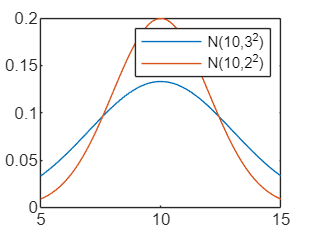

z = normpdf(x,10,2);
hold on % rárajzoló funkció
plot(x,z)
hold off
legend('N(10,3^2)','N(10,2^2)')

Binom(10,0.5)

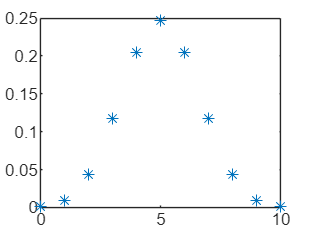

x = 0:10;
y = binopdf(x,10,0.5); % valószínűségek
plot(x,y,'*')

Adatok behívása.

load UStemps.mat
ustemp = readtable('UStemps.txt')

ustemp = 56×4 table
            City             JanTemp    Lat     Long 
    _____________________    _______    ____    _____

    {'Mobile, AL'       }      44       31.2     88.5
    {'Montgomery, AL'   }      38       32.9     86.8
    {'Phoenix, AZ'      }      35       33.6    112.5
    {'Little Rock, AR'  }      31       35.4     92.8
    {'Los Angeles, CA'  }      47       34.3    118.7
    {'San Francisco, CA'}      42       38.4      123
    {'Denver, CO'       }      15       40.7    105.3
    {'New Haven, CT'    }      22       41.7     73.4
    {'Wilmington, DE'   }      26       40.5     76.3
    {'Washington, DC'   }      30       39.7     77.5
    {'Jacksonville, FL' }      45         31     82.3
    {'Key West, FL'     }      65         25       82
    {'Miami, FL'        }      58       26.3     80.7
    {'Atlanta, GA'      }      37

ustemp.City

ans = 56×1 cell array
    {'Mobile, AL'       }
    {'Montgomery, AL'   }
    {'Phoenix, AZ'      }
    {'Little Rock, AR'  }
    {'Los Angeles, CA'  }
    {'San Francisco, CA'}
    {'Denver, CO'       }
    {'New Haven, CT'    }
    {'Wilmington, DE'   }
    {'Washington, DC'   }
    {'Jacksonville, FL' }
    {'Key West, FL'     }
    {'Miami, FL'        }
    {'Atlanta, GA'      }
    {'Boise, ID'        }
    {'Chicago, IL'      }
    {'Indianapolis, IN' }
    {'Des Moines, IA'   }
    {'Wichita, KS'      }
    {'Louisville, KY'   }
    {'New Orleans, LA'  }
    {'Portland, ME'     }
    {'Baltimore, MD'    }
    {'Boston, MA'       }
    {'Detroit, MI'      }
    {'Minneapolis, MN'  }
    {'St. Louis, MO'    }
    {'Helena, MT'       }
    {'Omaha, NE'        }
    {'Concord, NH'      }


Váltsunk át °F-ből °C-ba a JanTemp változó segítségével.

tempc = (ustemp.JanTemp -32)/1.8

tempc =     6.6667
    3.3333
    1.6667
   -0.5556
    8.3333
    5.5556
   -9.4444
   -5.5556
   -3.3333
   -1.1111


Átlag, szórás, medián, kvartilisek

mean(tempc) % átlag

ans = -3.0456

std(tempc) % szórás

ans = 7.4332

median(tempc) % medián

ans = -4.1667

quantile(tempc, [.25 .75])

ans =    -7.5000    0.8333


Melyik városban volt a leghidegebb?

ustemp.Celsius = tempc;
m = min(tempc);
ind = find(tempc == m)

ind = 37

ustemp(ind, 'City')

ans = table
          City      
    ________________

    {'Bismarck, ND'}


Hisztogram - gyakorisági

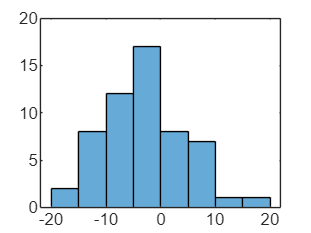

histogram(ustemp.Celsius)

Sűrűségi hisztogram

histogram(ustemp.Celsius,'Normalization','pdf')

Illesszünk normális sfv-t.

% megbecsüljük a normális eloszlás paramétereit
[m s] = normfit(ustemp.Celsius)

m = -3.0456

s = 7.4332

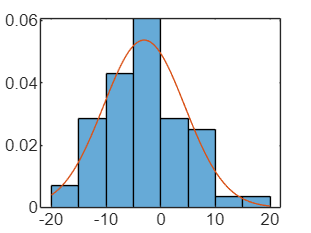

hold on
x = linspace(-20,20);
y = normpdf(x,m,s);
plot(x,y)
hold off

Doboz-ábra.

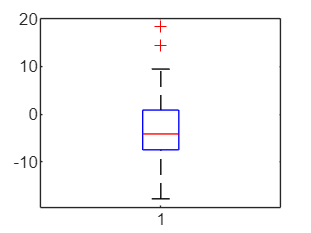

boxplot(ustemp.Celsius)

Szélességi fokok alapján osszuk 2felé a városokat.

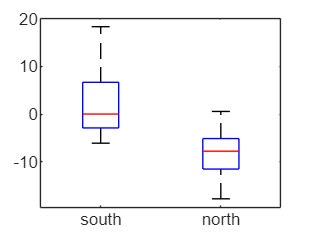

m = median(ustemp.Lat);
osztaly = m<ustemp.Lat;
osztaly = categorical(osztaly,[0 1],{'south','north'});
boxplot(ustemp.Celsius, osztaly)

Ugyanez hosszúsági fokra.

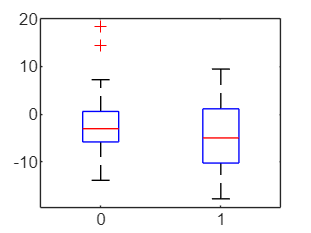

m = median(ustemp.Long);
osztaly = m<ustemp.Long;
boxplot(ustemp.Celsius, osztaly)